## **LOAD IMAGE**

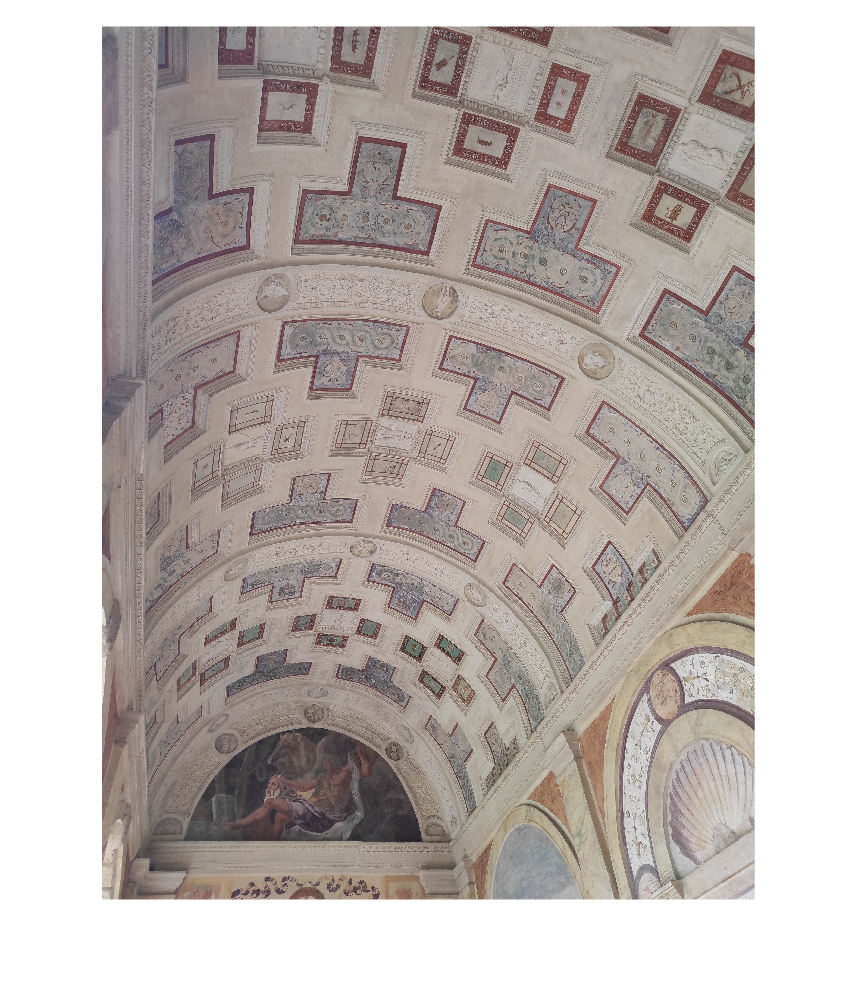

clear all;
im = imread('PalazzoTe.jpg');

%rotate the image
img=imrotate(im, -90);

%show the image
imshow(img);

## **LOAD NECESSARY GEOMETRIC ELEMENTS**

center1=load('elements\CONICS\centerC1.mat').center1;
center2=load('elements\CONICS\centerC2.mat').center2;


% IMPORTANT: p1,p2,p3,p4 are computed in 
% Question 5 so run Question 5
% before this
p1=load('elements\CONIC C1 POINTS\pa.mat' ).p1;
p2=load('elements\CONIC C1 POINTS\pb.mat').p2;
p3=load('elements\CONIC C2 POINTS\pa.mat' ).p3;
p4=load('elements\CONIC C2 POINTS\pb.mat').p4;

K=load('elements\CALIBRATION MATRIX\K.mat').K;
H=load('elements\HOMOGRAPHIES\HORIZONTAL PLANE\H.mat').H;

## **Shape reconstruction of the points  using the homography of the axial plane**

% Shape reconstruction homography
Hsr=inv(H);

% Turn the the circumferences' centers
center1=Hsr*center1;
center2=Hsr*center2;


% Turn the points
p1=Hsr*p1;
p2=Hsr*p2;
p3=Hsr*p3;
p4=Hsr*p4;


% Normalize
center1=center1./center1(3);
center2=center2./center2(3);
p1=p1./p1(3);
p2=p2./p2(3);
p3=p3./p3(3);
p4=p4./p4(3);

## **Computation of the roto-translation matrix responsible for the mapping axial plane-3D world**

i_j_o=inv(K)*H;
i_p=i_j_o(:,1);
j_p=i_j_o(:,2);
o_p=i_j_o(:,3);


R_t=[i_p , j_p , cross(i_p,j_p) , o_p ;
               0,0,0,1]

R_t =    -0.7492    1.3329   -0.3962   -0.4571
   -0.9677   -0.7294   -1.4987   -0.7111
   -0.9515   -0.3077    1.8363    1.0000
         0         0         0    1.0000


## **Express points in the axial plane using a 3D frame system by adding the coordinate z=0**

C1=[center1(1);
    center1(2);
    0;
    center1(3)];


C2=[center2(1);
    center2(2);
    0;
    center2(3)];

p1=[p1(1);
    p1(2);
    0;
    p1(3)];
p2=[p2(1);
    p2(2);
    0;
    p2(3)];
p3=[p3(1);
    p3(2);
    0;
    p3(3)];
p4=[p4(1);
    p4(2);
    0;
    p4(3)];



## **Apply the roto-translation matrix to the points **



C1_w=R_t*C1;
C2_w=R_t*C2;
C1_w=C1_w./C1_w(4);
C2_w=C2_w./C2_w(4);

p1=R_t*p1;
p1=p1./p1(4);
p2=R_t*p2;
p2=p2./p2(4);
p3=R_t*p3;
p3=p3./p3(4);
p4=R_t*p4;
p4=p4./p4(4);

## **Plot the result **

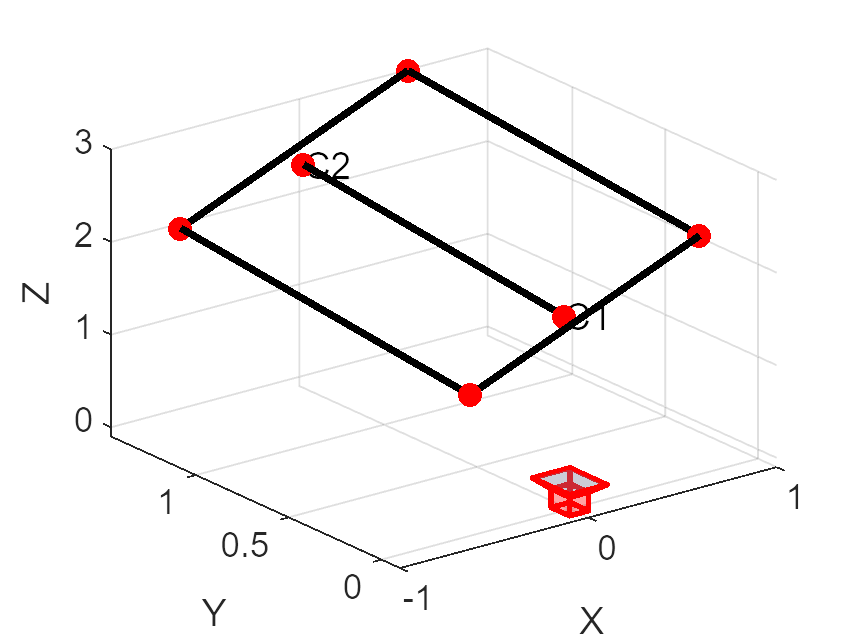

camera_rotation=[1,0,0;
                 0,1,0;
                 0,0,1];
camera_center=[0;0;0];
figure;
scatter3(C2_w(1) , C2_w(2), C2_w(3)  ,'o', 'filled', 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r')
hold on;
scatter3(C1_w(1) , C1_w(2), C1_w(3)  ,'o', 'filled', 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r')
hold on;
scatter3(p1(1) , p1(2), p1(3)  ,'o', 'filled', 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r')
hold on
scatter3(p2(1) , p2(2), p2(3)  ,'o', 'filled', 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r')
hold on
scatter3(p3(1) , p3(2), p3(3)  ,'o', 'filled', 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r')
hold on
scatter3(p4(1) , p4(2), p4(3)  ,'o', 'filled', 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r')
hold on
plotCamera('location', camera_center.', 'orientation', camera_rotation, 'size', 0.1);
hold on;
plot3([C2_w(1), C1_w(1)], [C2_w(2), C1_w(2)], [C2_w(3), C1_w(3)], 'k-', 'LineWidth', 2);
hold on;
plot3([p1(1), p2(1)], [p1(2), p2(2)], [p1(3), p2(3)], 'k-', 'LineWidth', 2);
hold on ;
plot3([p3(1), p4(1)], [p3(2), p4(2)], [p3(3), p4(3)], 'k-', 'LineWidth', 2);
hold on;
plot3([p1(1), p3(1)], [p1(2), p3(2)], [p1(3), p3(3)], 'k-', 'LineWidth', 2);
hold on;
plot3([p2(1), p4(1)], [p2(2), p4(2)], [p2(3), p4(3)], 'k-', 'LineWidth', 2);
hold on
text( C1_w(1) , C1_w(2), C1_w(3),'C1')
hold on
text( C2_w(1) , C2_w(2), C2_w(3),'C2')


xlabel('X');ylabel("Y");zlabel("Z")

hold off;

## **Compute the orientation of the vector C1C2**

point1 = C1_w(1:3); 
point2 = C2_w(1:3);

direction_vector = C2_w(1:3) - C1_w(1:3);

[degree_x , degree_y, degree_z]=orientation_3d(direction_vector);

angle_x = 103.0367

angle_y = 38.9193

angle_z = 54.1030